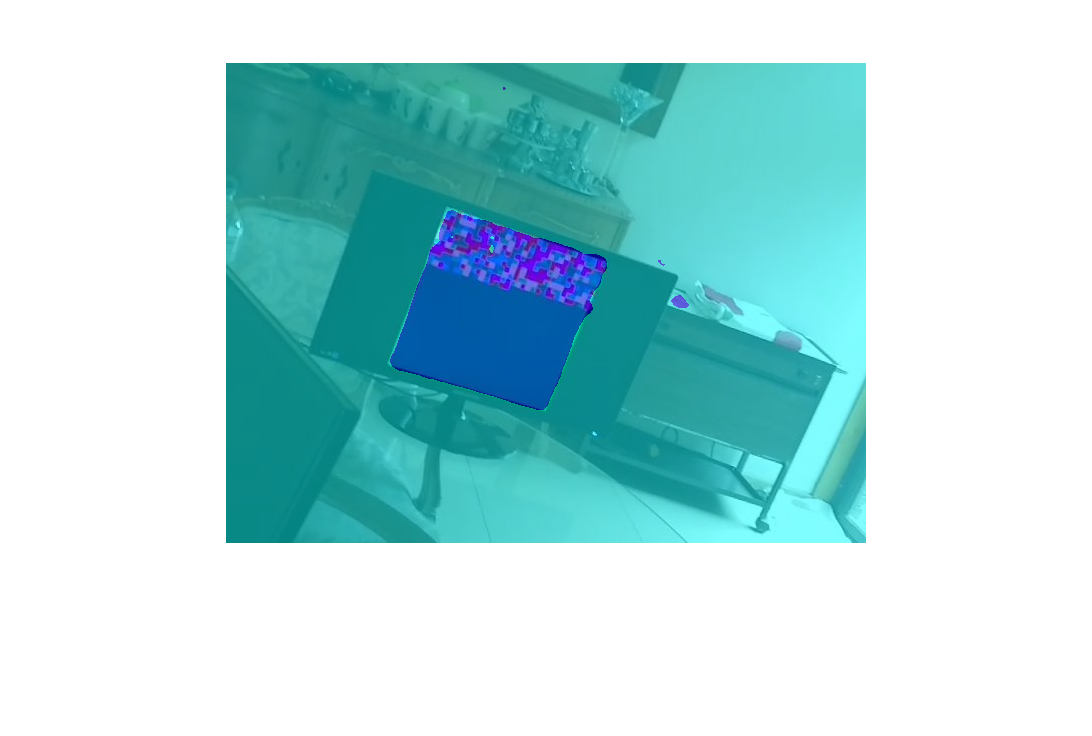

% segment frame from the image

load("net.mat")
% I = imread("../Training data/3.jpg");
I = imread("imageCaptured\8.jpg");
C = semanticseg(I, net);
B = labeloverlay(I,C);
figure;
imshow(B)

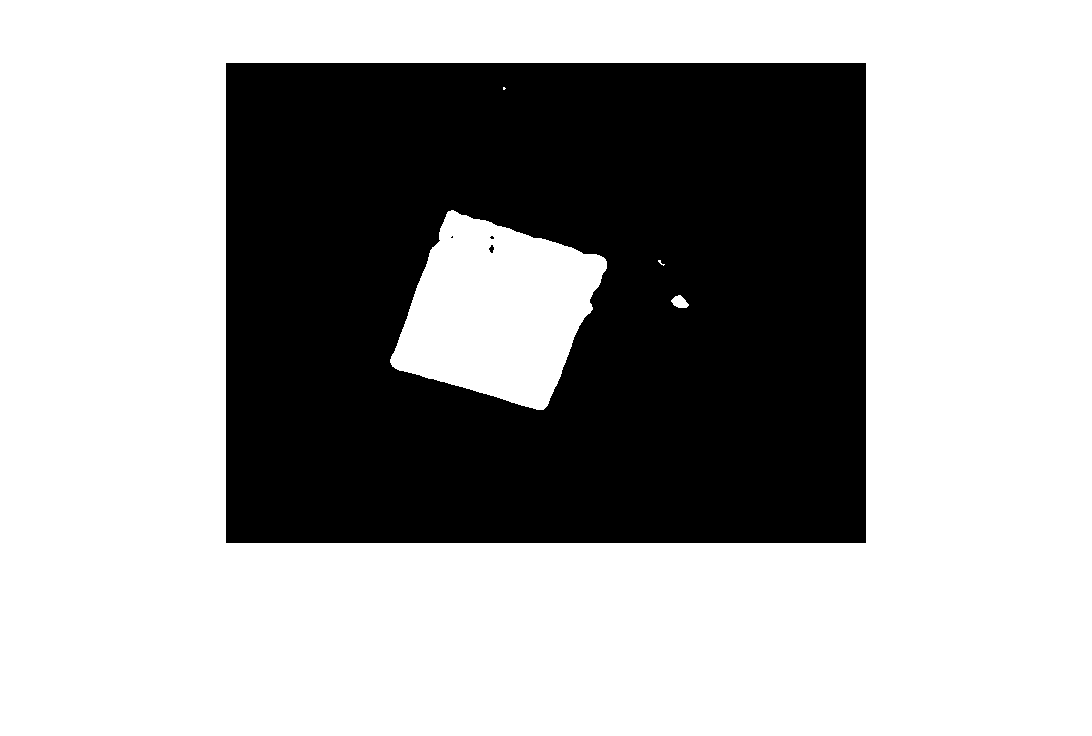

featureMap = (C== 'Frame'); % Create a logical matrix of the feature map
imshow(featureMap)


% [labeledImage, numberOfBlobs] = bwlabel(featureMap);
% blobMeasurements = regionprops(labeledImage, 'area', 'Centroid');
% % Get all the areas
% allAreas = [blobMeasurements.Area]; % No semicolon so it will print to the command window.
% menuOptions{1} = '0'; % Add option to extract no blobs.
% % Display areas on image
% for k = 1 : numberOfBlobs           % Loop through all blobs.
%   thisCentroid = [blobMeasurements(k).Centroid(1), blobMeasurements(k).Centroid(2)];
%   message = sprintf('Area = %d', allAreas(k));
%   text(thisCentroid(1), thisCentroid(2), message, 'Color', 'r');
%   menuOptions{k+1} = sprintf('%d', k);
% end

numberToExtract = 1;
% sizeOption = 'Largest';

featureMap = ExtractNLargestBlobs(featureMap, numberToExtract);


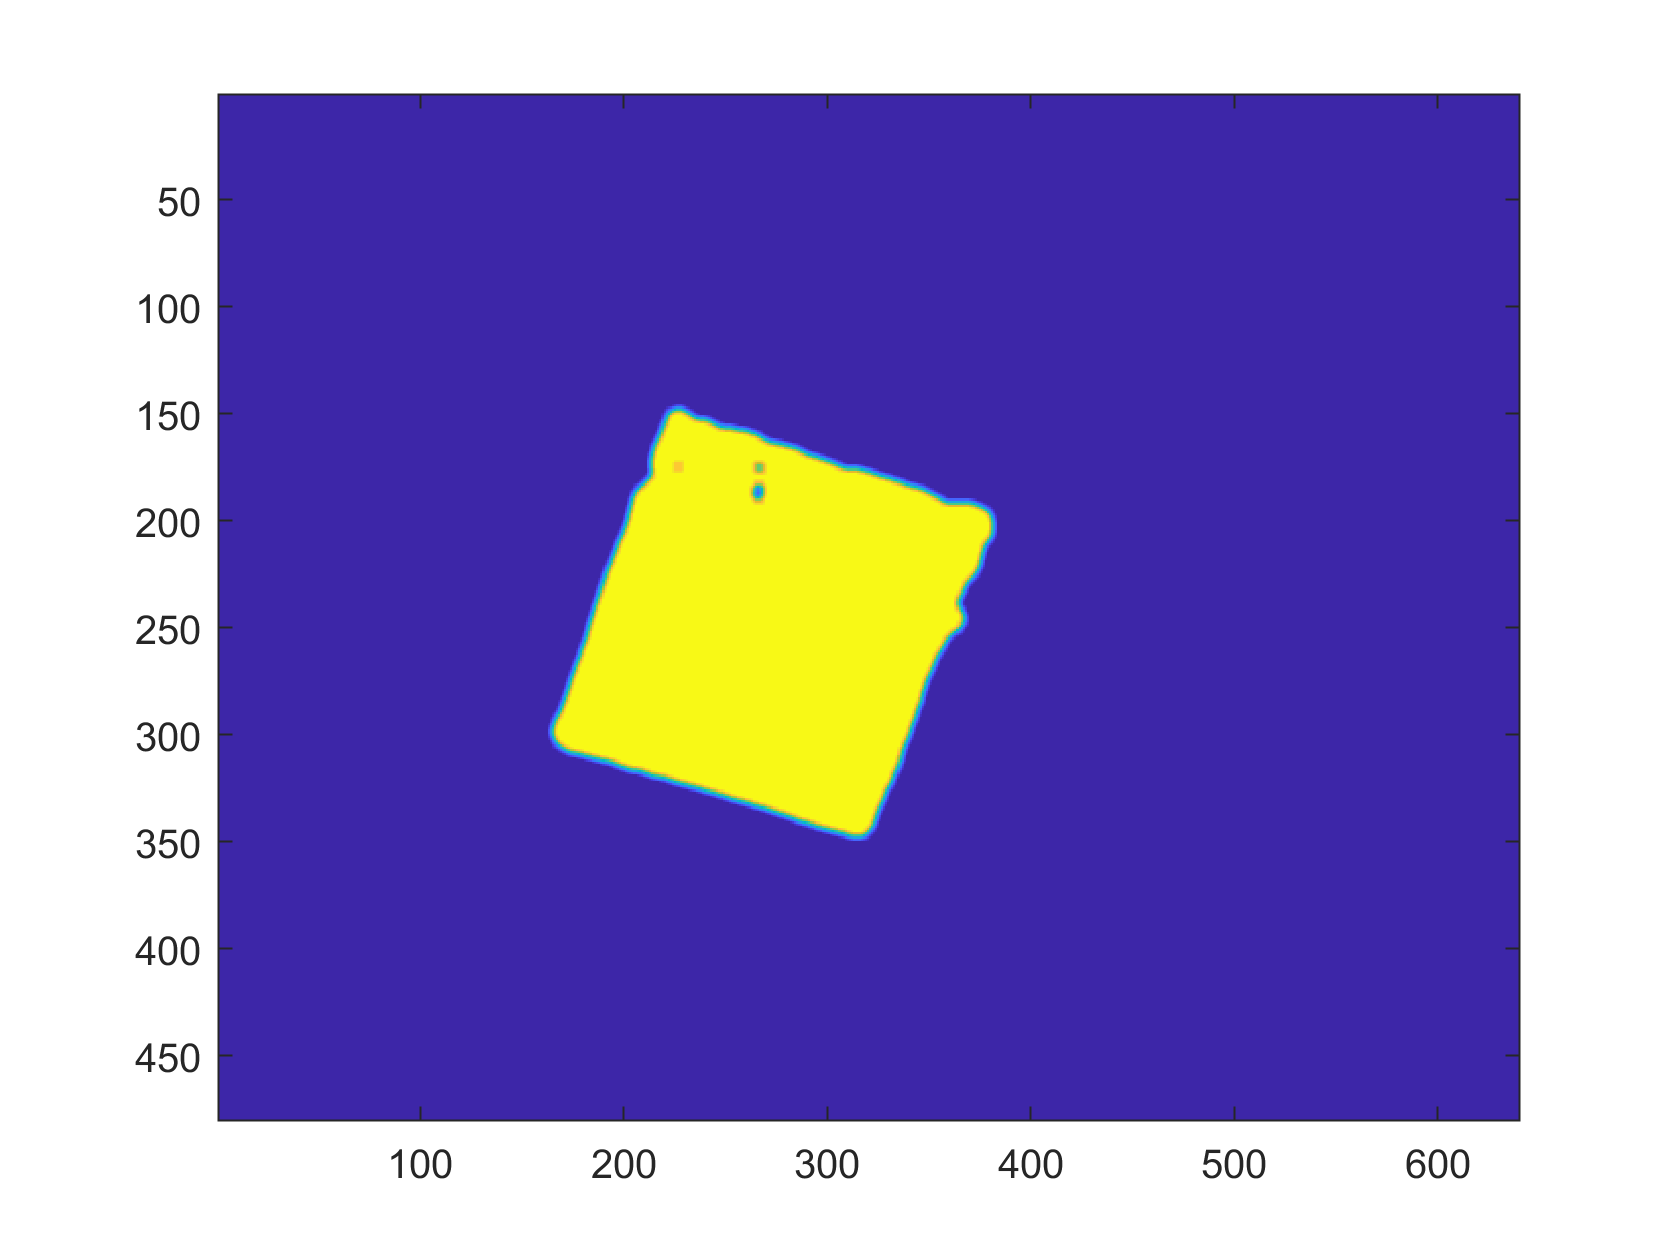

% featureMap = edge(featureMap,"approxcanny");  % extract perimeter of frame (maybe lose if acc low)

K = (1/25)*ones(5); % smooth factor
featureMap = conv2(featureMap,K,'same');

figure;
image(featureMap.*255)  % display feature map

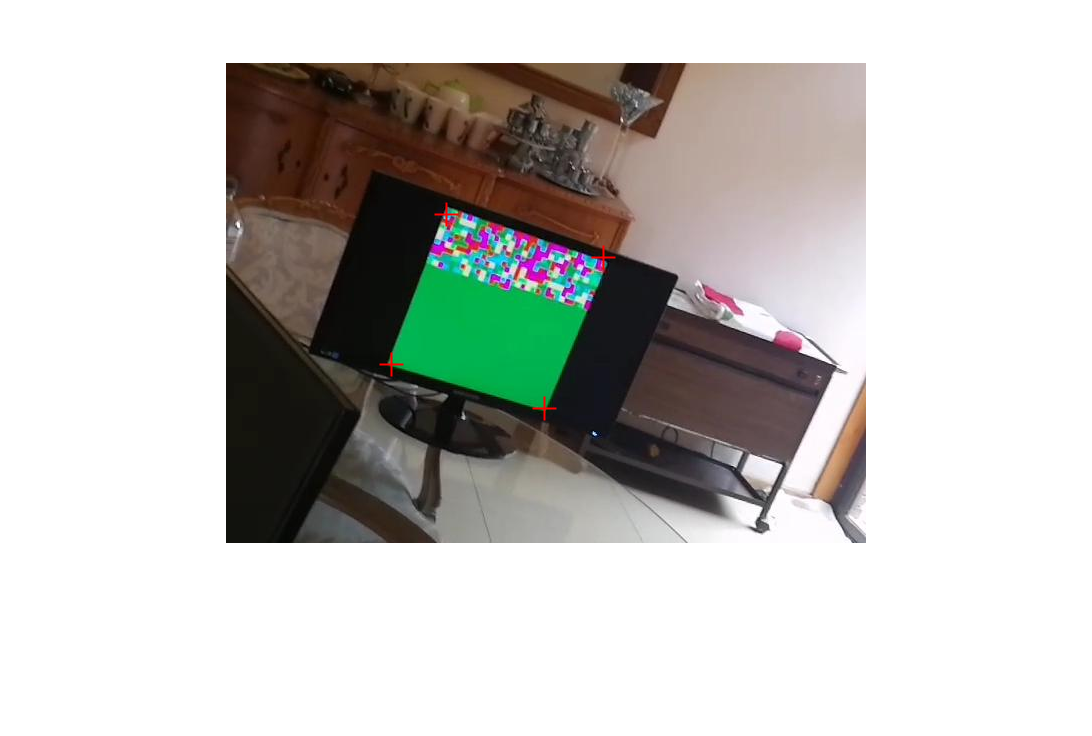


[featureMap,J]=find(featureMap>max(featureMap(:))/2);
IJ=[featureMap,J];
[~,idx]=min(IJ*[1 1; -1 -1; 1 -1; -1 1].');
corners=IJ(idx,:);

% display corners of the frame superimposed over the image
imshow(I)
hold on
plot(corners(1,2),corners(1,1),'r+')
plot(corners(2,2),corners(2,1),'r+')
plot(corners(3,2),corners(3,1),'r+')
plot(corners(4,2),corners(4,1),'r+')
hold off

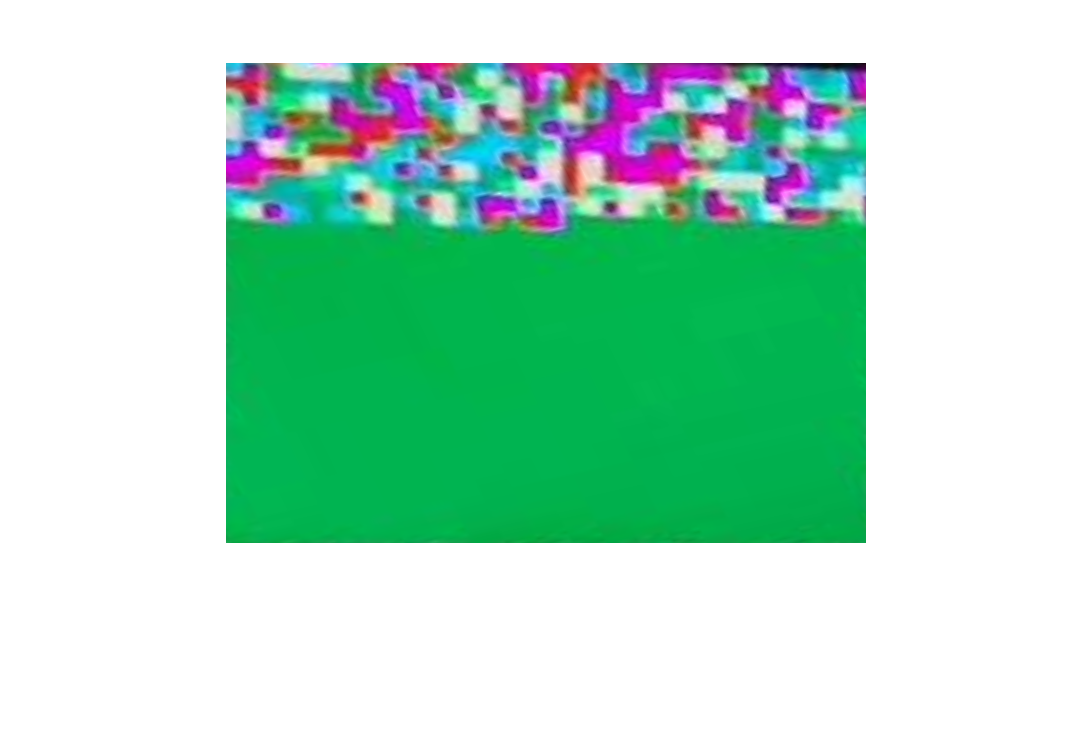

% Apply Perspective Warping followed by cropping of the frame 
movingPoints = [corners(1,2) corners(1,1); corners(3,2),corners(3,1); corners(2,2),corners(2,1); corners(4,2),corners(4,1)];%coordinate of distorted corners 
fixedPoints=[0 0;size(I,1) 0;size(I,1) size(I,2);0 size(I,2)]; %coordinate of image's corners

tform = fitgeotrans(movingPoints,fixedPoints,'projective');
R=imref2d(size(I),[1 size(I,1)],[1 size(I,2)]);
frame=imwarp(I,tform,'OutputView',R);

figure
imshow(frame);

% Apply grid for visual analysis (Remove for final code)
numSymbols = 20;
figure
imshow(frame);
axis on;
[rows, columns, numberOfColorChannels] = size(frame)

rows = 480

columns = 640

numberOfColorChannels = 3

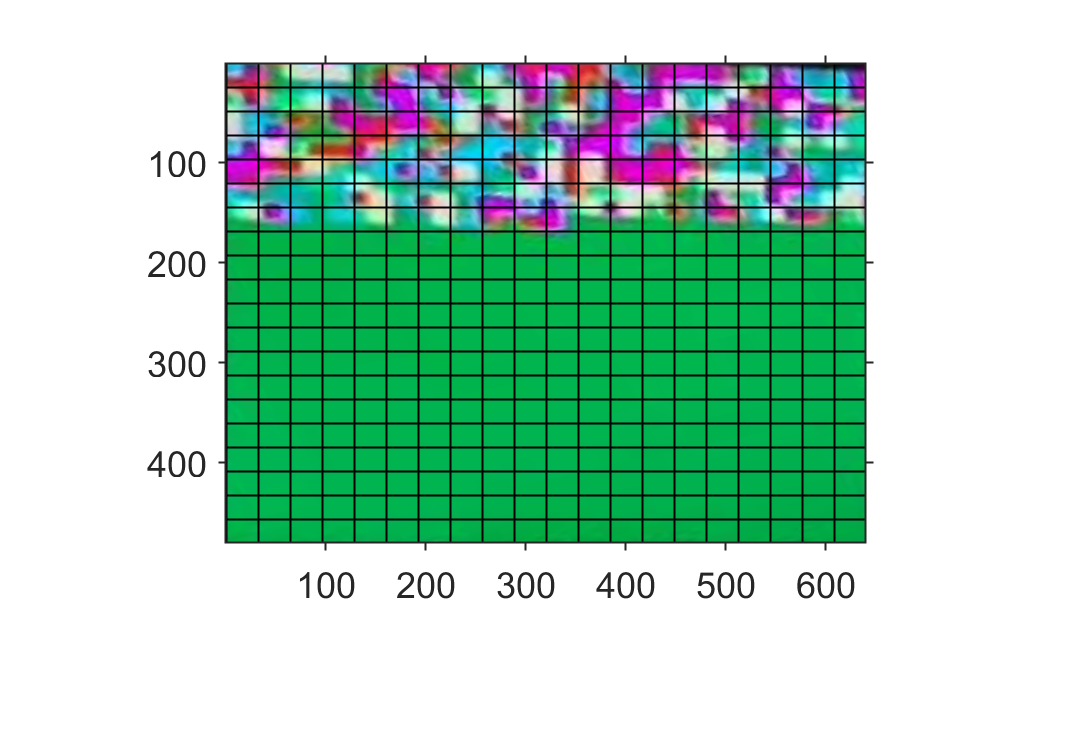

hold on;
for row = 1 : rows/numSymbols : rows
  line([1, columns], [row, row], 'Color', 'k');
end
for col = 1 : columns/numSymbols : columns
  line([col, col], [1, rows], 'Color', 'k');
end

% Divide Frames into symbols
[rows columns numberOfColorBands] = size(frame);
blockSizeR = rows/numSymbols; % Rows in block.
blockSizeC = columns/numSymbols; % Columns in block.

wholeBlockRows = floor(rows / blockSizeR);
blockVectorR = [blockSizeR * ones(1, wholeBlockRows), rem(rows, blockSizeR)] ;
blockVectorR = blockVectorR(1:numSymbols);
% Figure out the size of each block in columns.
wholeBlockCols = floor(columns / blockSizeC);
blockVectorC = [blockSizeC * ones(1, wholeBlockCols), rem(columns, blockSizeC)];
blockVectorC = blockVectorC(1:numSymbols);
symbols = mat2cell(frame, blockVectorR, blockVectorC, numberOfColorBands)

symbols = 20×20 cell array
    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}
    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}
    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}  

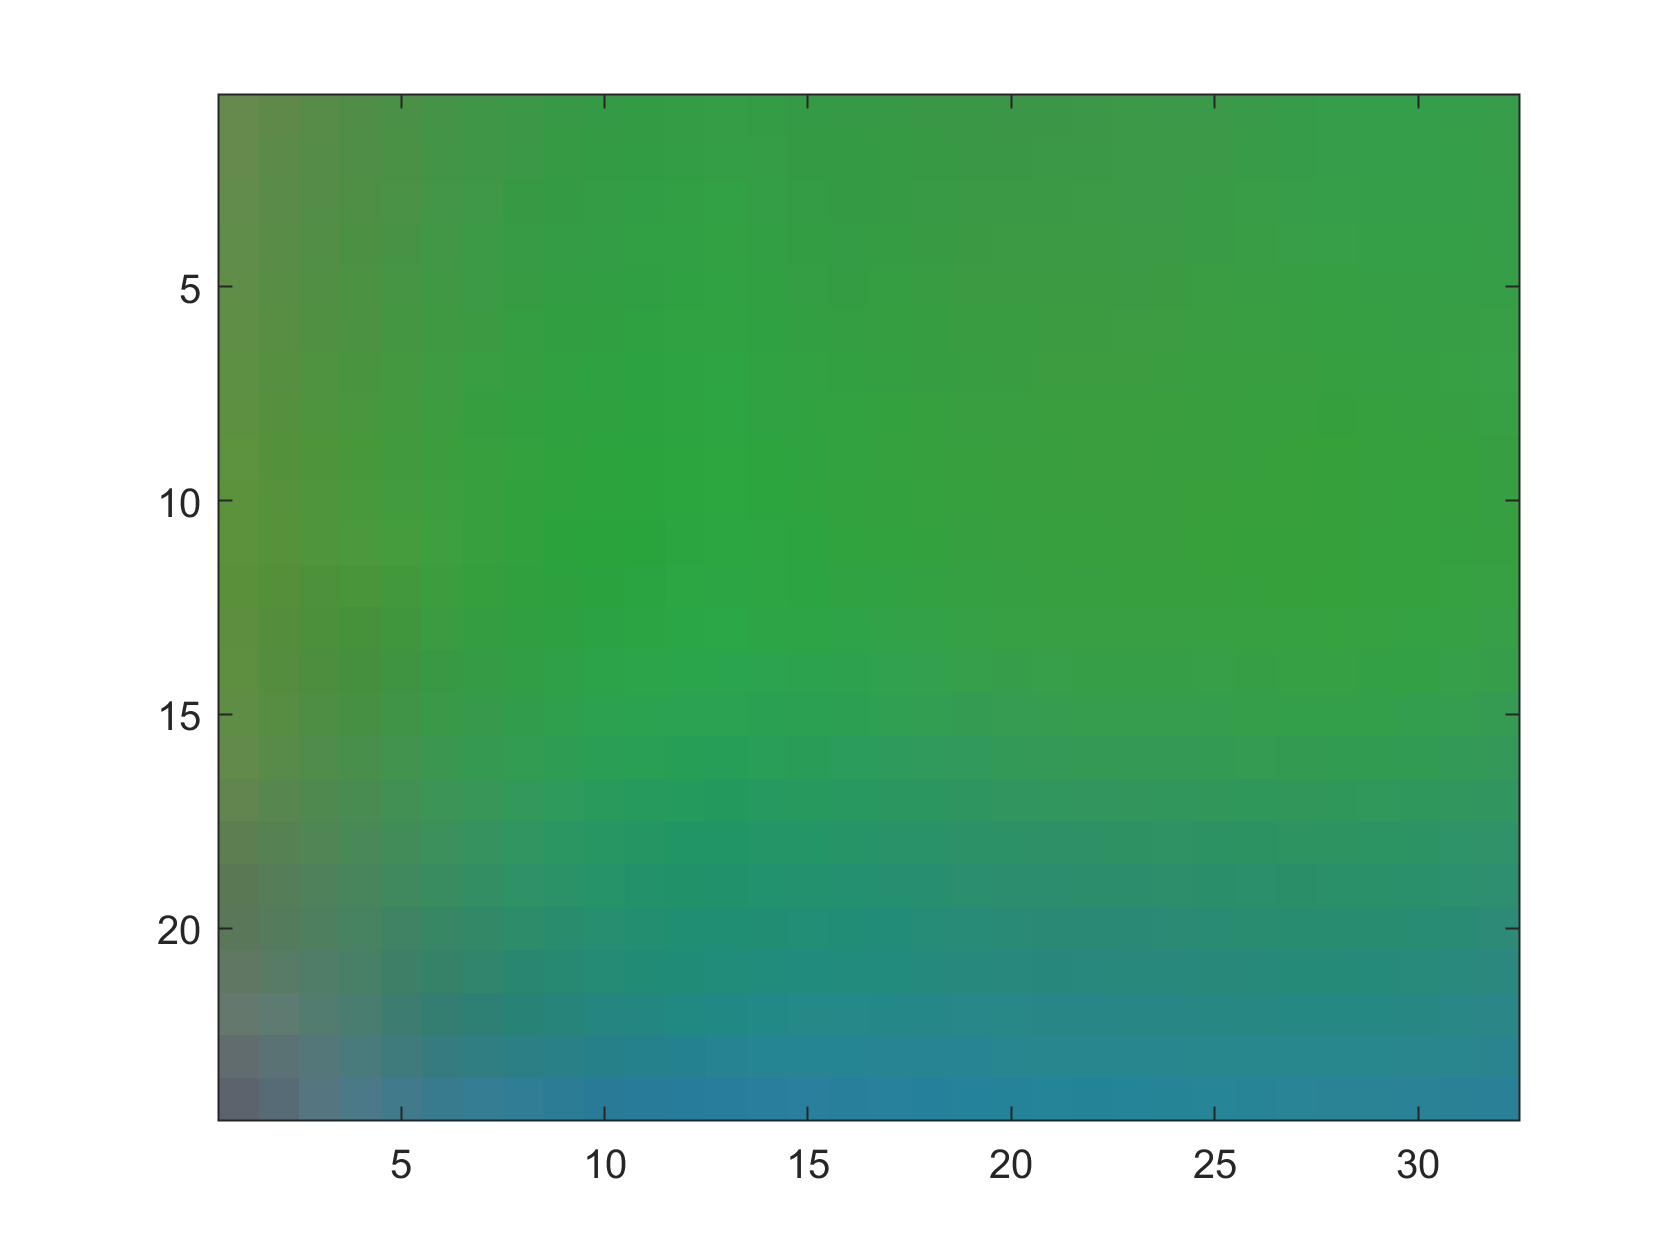


% display one symbol
symbol1 = cell2mat(symbols(1,2));
figure
image(symbol1)


R = mean2(symbol1(:,:,1))

R = 53.7943

G = mean2(symbol1(:,:,2))

G = 149.7253

B = mean2(symbol1(:,:,3))

B = 84.2578


XYZ  = rgb2xyz([R/255,G/255,B/255],'WhitePoint','D65','ColorSpace','sRGB')

XYZ =     0.1398    0.2315    0.1217


% XYZ = xyz2rgbwide(XYZ)
x = XYZ(1)/(XYZ(1)+XYZ(2)+XYZ(3))

x = 0.2836

y = XYZ(2)/(XYZ(1)+XYZ(2)+XYZ(3))

y = 0.4695

xyz2rgb(XYZ).*255

ans =    53.7943  149.7253   84.2578



lab = rgb2lab([R/255,G/255,B/255])

lab =    55.2228  -43.0491   26.4588


C = makecform('srgb2lab');
lab = applycform([R/255,G/255,B/255],C)

lab =    55.2078  -40.5928   25.9178



rowVals = [];
colVals = [];
 oneSymbol = symbol1;
        meanR = mean2(oneSymbol(:,:,1));
        meanG = mean2(oneSymbol(:,:,2));
        meanB = mean2(oneSymbol(:,:,3));
        
        XYZ = rgb2xyz([meanR/255,meanG/255,meanB/255]);
        CC = makecform('xyz2xyl');
        xy = applycform(XYZ,CC)

xy =     0.2836    0.4695    0.2315


        
        % 0.34
        
        if xy(1) > 0.34
            rowVals = [rowVals,xy(1) + xy(3)]
        else
            rowVals = [rowVals,xy(1) - xy(3)]
        end

rowVals = 0.0522

        
        if xy(2) > 0.34
            colVals = [colVals,xy(2) + xy(3)]
        else
            colVals = [colVals,xy(2) - xy(3)]
        end

colVals = 0.7010

   symbols  = image2symbols(I, net, 20)

corners =     89   180
   437   489
   111   502
   417   159


symbols = 20×20 cell array
    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}
    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}
    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}  

symbols = 20×20 cell array
    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}
    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}
    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}    {24×32×3 uint8}  


CC = makecform('xyz2xyl')

CC = struct with fields:
            c_func: @xyz2xyl
     ColorSpace_in: 'xyz'
    ColorSpace_out: 'xyl'
          encoding: 'double'
             cdata: [1×1 struct]


applycform(XYZ,CC)

ans =     0.2932    0.5420    0.1972



% 
% rgbvalue = uint16([R,G,B])
% xyzvalue = rgbwide2xyz(rgbvalue,10)
% x = xyzvalue(1)/(xyzvalue(1)+xyzvalue(2)+xyzvalue(3))
% y = xyzvalue(2)/(xyzvalue(1)+xyzvalue(2)+xyzvalue(3))


% xyz_primaries = rgb2xyz([R/255 G/255 B/255])
% xyzMag = sum(xyz_primaries,2)
% x_primary = xyz_primaries(:,1)./xyzMag
% y_primary = xyz_primaries(:,2)./xyzMag


[x,y] = findxy(symbols)

x =     0.4904   -0.4148    0.7590    0.7507    0.5038    0.4683    0.7533    0.4529    0.4814   -0.3608    0.5445    0.9332    0.9688    0.2980    0.7894    0.5757    0.4737    0.7035    0.2537    0.4565    0.4664    0.4662    0.0719    0.2728    0.8252    0.4502    0.5644    0.9400    0.5029    0.5459    0.4516    0.5482    0.5332    0.5007    0.5528    0.6591    0.4494    0.1137    0.8272    0.7804    0.8833    0.4582    0.4283    0.5548    0.7770    0.9949    0.7736    0.5120    0.5496    0.5039


y =     0.3448   -0.3561    0.8321    0.8328    0.3138    0.3737    0.8268    0.5104    0.3619   -0.3341    0.1582   -0.1011   -0.1319    0.3671    0.0068    0.1184    0.3517    0.7873    0.3525    0.3186    0.4979    0.3453    0.4332    0.3985    0.9132    0.5156    0.4046   -0.1034    0.3328    0.3826    0.3611    0.1562    0.1590    0.1916    0.3881    0.7090    0.4912    0.4343   -0.0325    0.8763   -0.0492    0.3858    0.5363    0.3978    0.8560   -0.1665    0.8506    0.3265    0.1479    0.3134


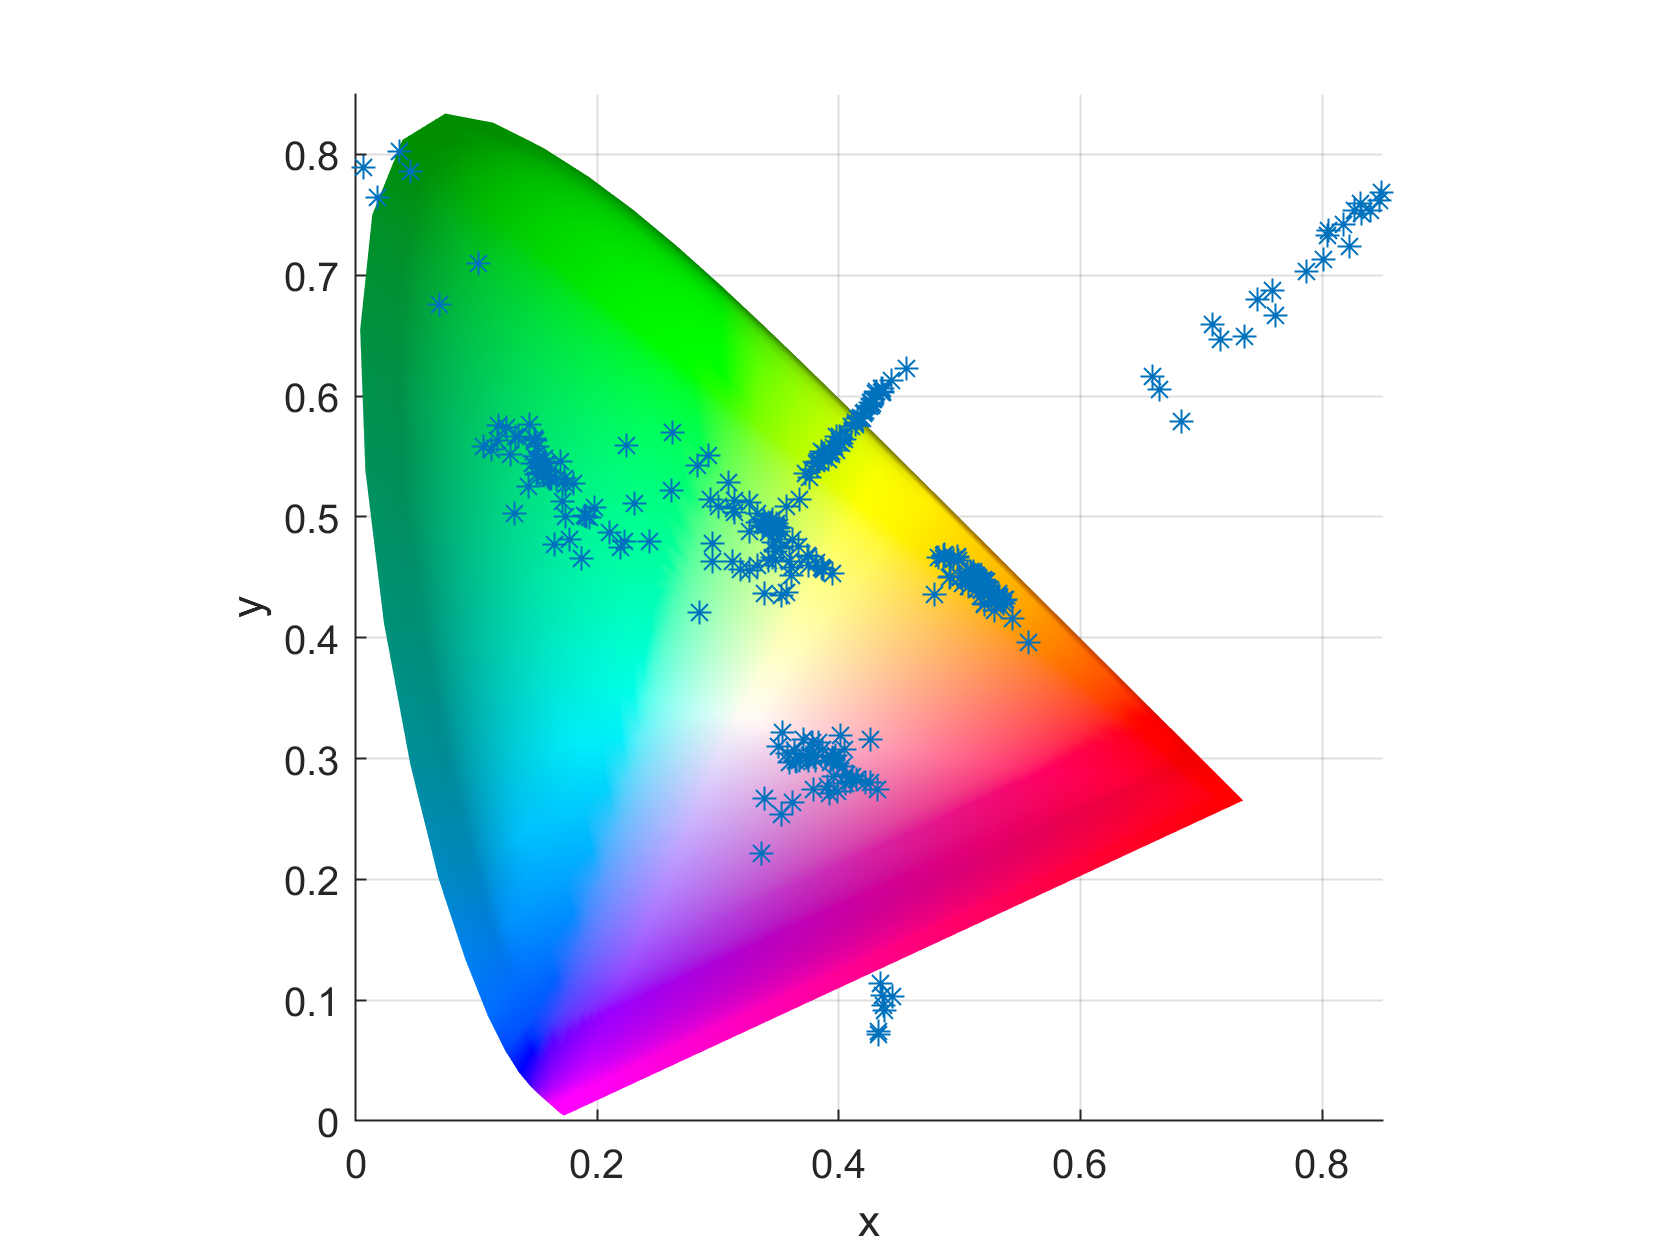

figure;
plotChromaticity();
hold on;
plot(y,x,'*');
hold off

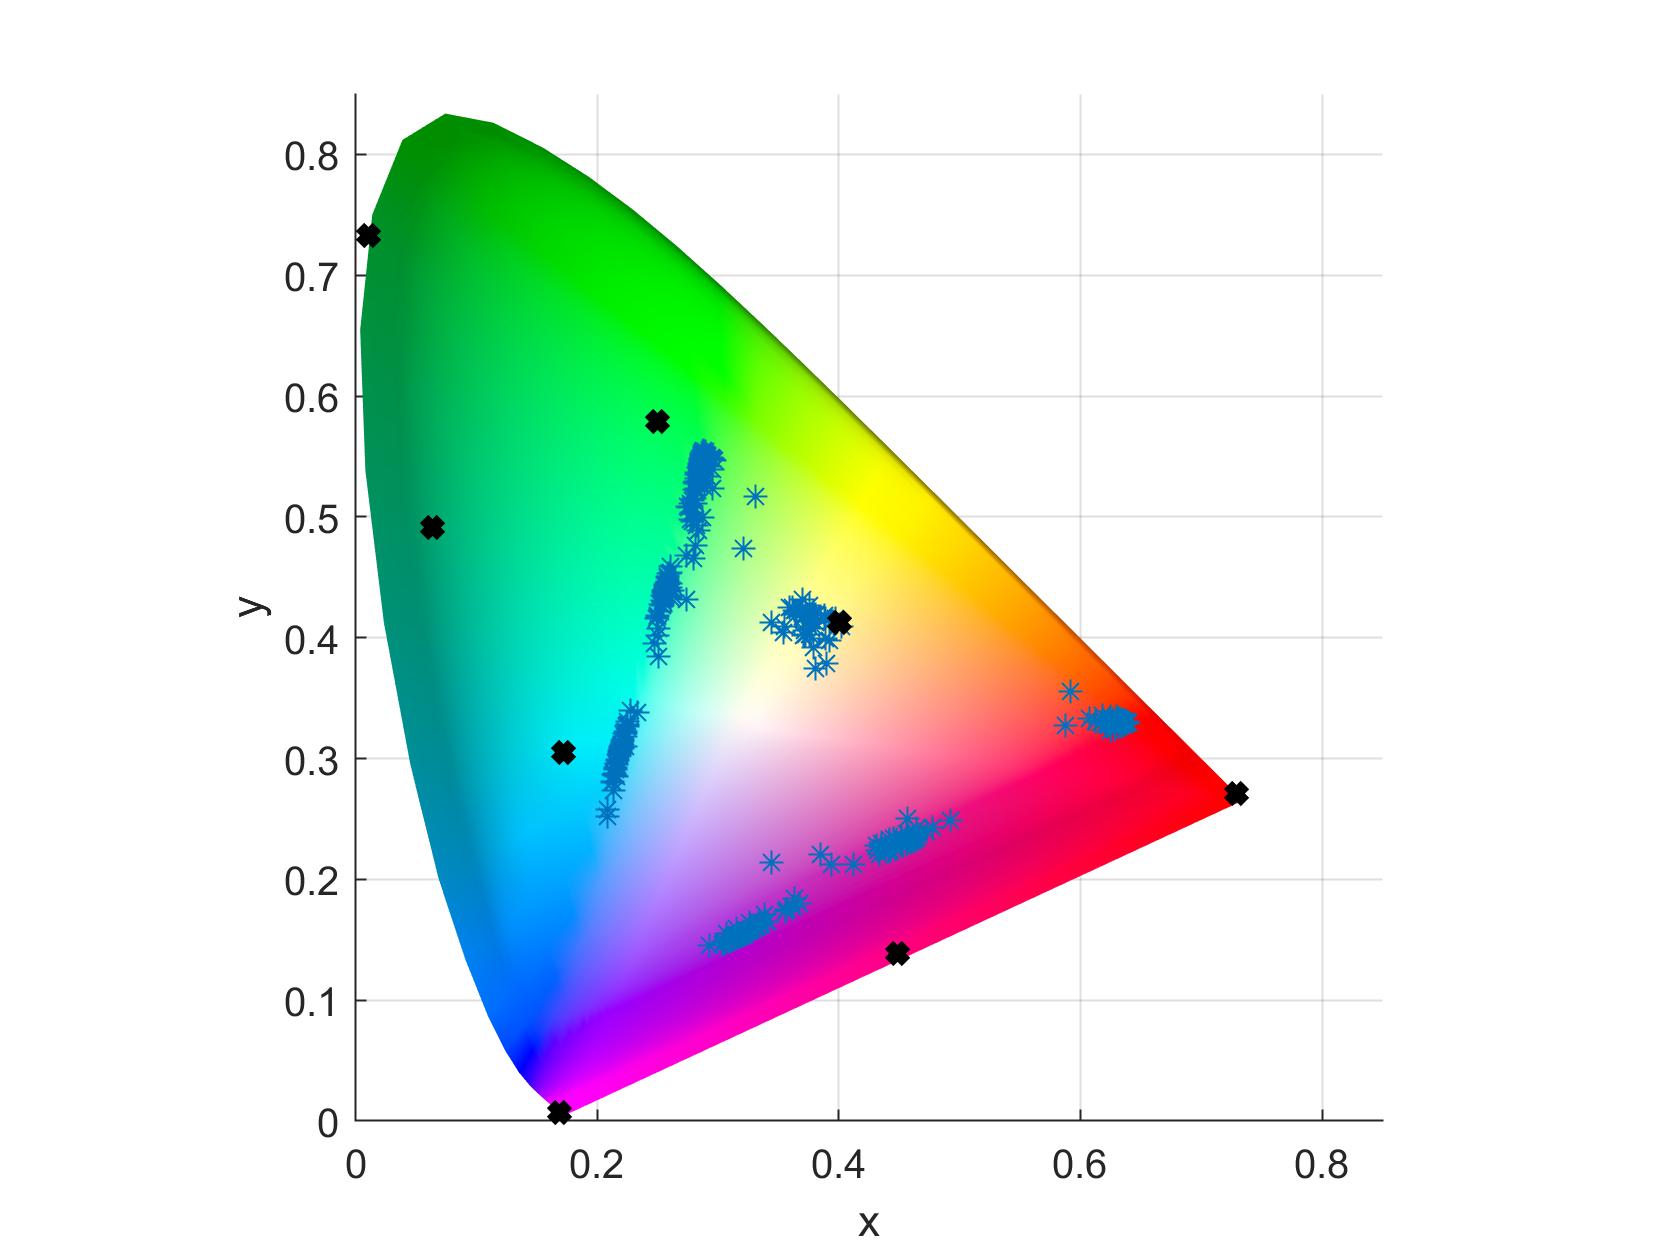

% Categorize colours
% symbol1(12,16,:);
% meanR = mean(mean(symbol1(:,:,1)));
% meanG = mean(mean(symbol1(:,:,2)));
% meanB = mean(mean(symbol1(:,:,3)));
% 
% %take inner two eights of symbol 
% meanR = mean(mean(symbol1(9:15,12:20,1)))
% meanG = mean(mean(symbol1(9:15,12:20,2)))
% meanB = mean(mean(symbol1(9:15,12:20,3)))
% 
% XYZ = rgb2xyz([meanR,meanG,meanB]);
% x = XYZ(1)/(XYZ(1)+XYZ(2)+XYZ(3));
% y = XYZ(2)/(XYZ(1)+XYZ(2)+XYZ(3));
% 
% xideal = 0.1725;
% yideal = 0.3052;

xideal = [0.011 0.06367 0.2503 0.4008 0.169 0.1725 0.449 0.729];
yideal = [0.733,0.491, 0.579, 0.4127, 0.007, 0.3052, 0.139, 0.271];
[rowVals, colVals] = generatePointsCIE(symbols);
% convert RGB value to integer for signal constellation and used knn to
figure;
plotChromaticity();
hold on;
plot(rowVals,colVals,'*');
plot(xideal, yideal,'kx','LineWidth',3);
hold off

foundPoints = [colVals; rowVals;]'; % (x,y)
realPoints  = [0.011 0.06367 0.2503 0.4008 0.169 0.1725 0.449 0.729; 0.733,0.491, 0.579, 0.4127, 0.007, 0.3052, 0.139, 0.271 ]';

% A = rand(1,2)
% B = rand(10,2)
% %compute Euclidean distances:
% distances = sqrt(sum(bsxfun(@minus, B, A).^2,2))
% %find the smallest distance and use that as an index into B:
% closest = B(find(distances==min(distances)),:)
% figure;
% plot(A(1),A(2),'*')
% hold on
% plot(B(:,1)', B(:,2)','kx','LineWidth',3);

[k,dist] = dsearchn(realPoints, foundPoints);

assumedPoints = []; %zeros(400,2)
for i = 1:1:200
    assumedPoints = [assumedPoints; realPoints(k(i),:)];
end


hold off

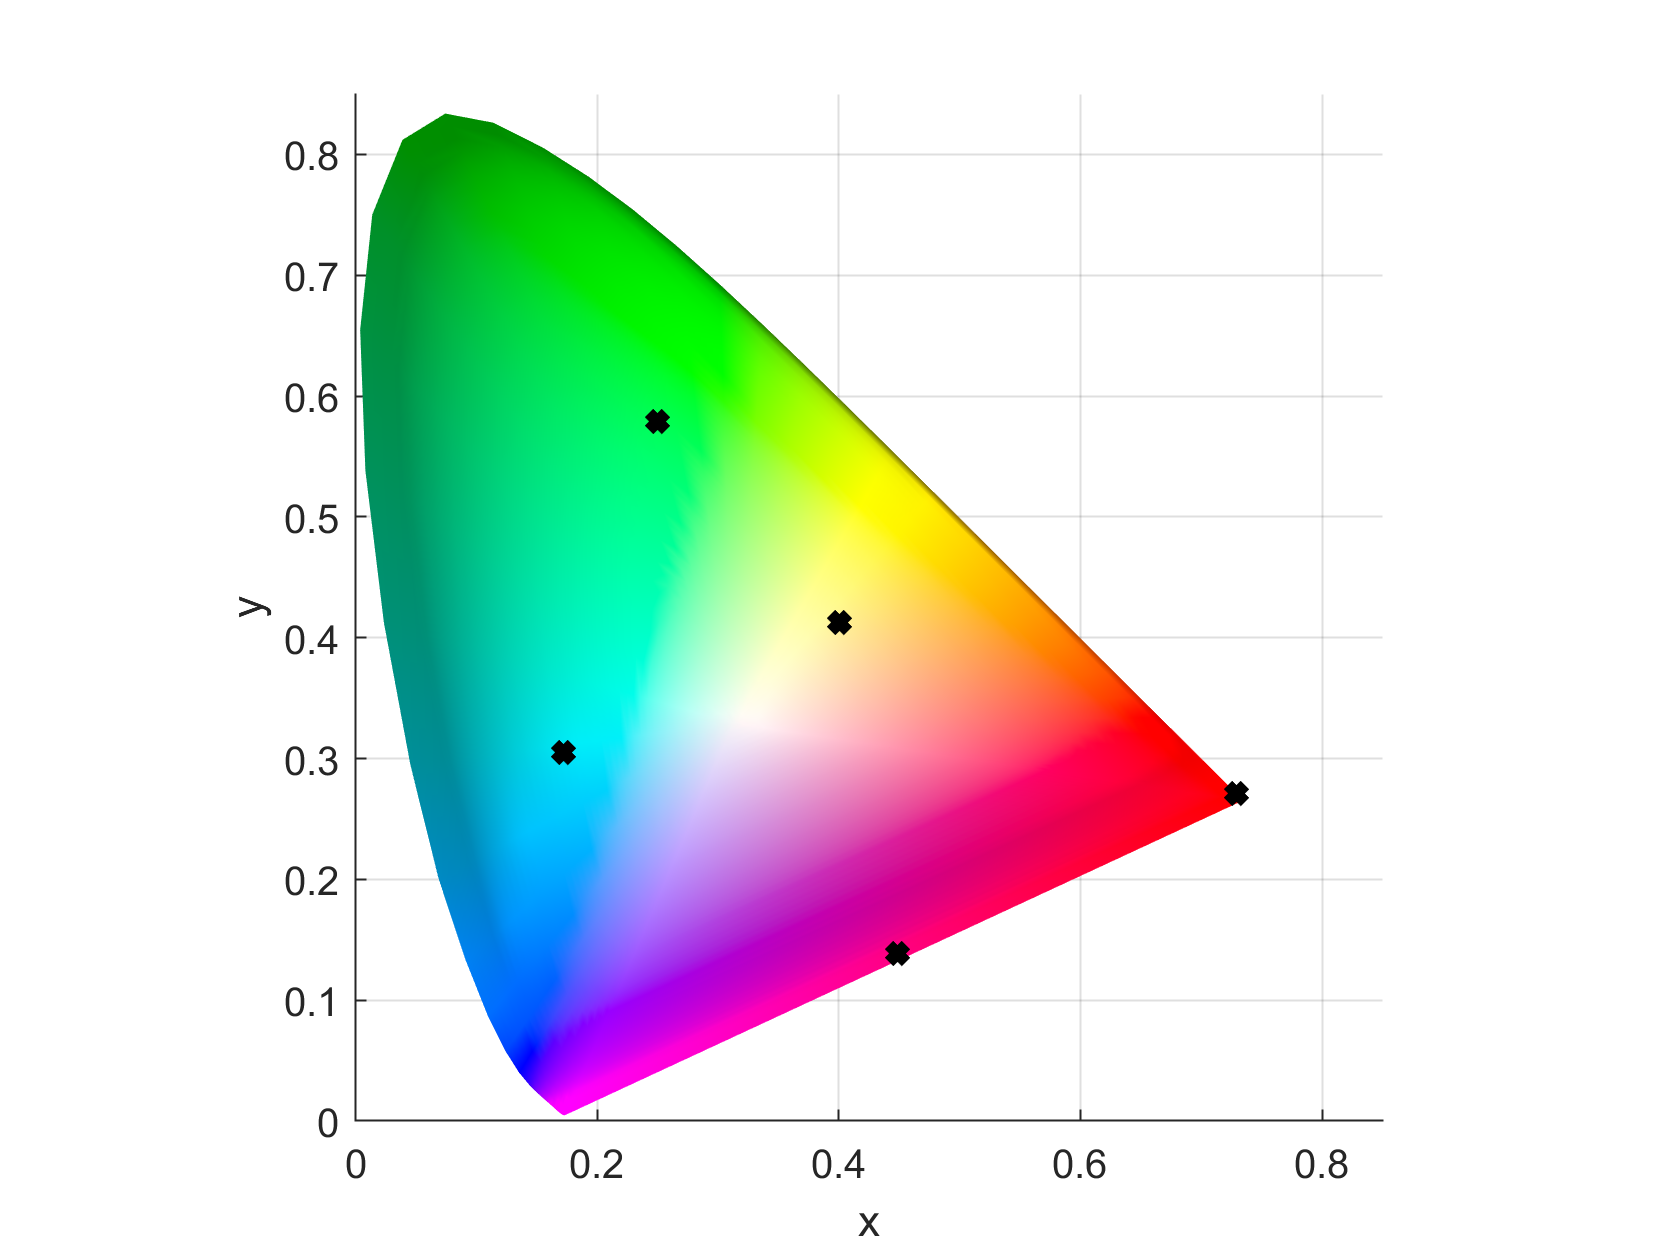

figure;
plotChromaticity();
hold on;
plot(assumedPoints(:,1), assumedPoints(:,2),'kx','LineWidth',3);
hold off

% Function to return the specified number of largest or smallest blobs in a binary image.
% If numberToExtract > 0 it returns the numberToExtract largest blobs.
% If numberToExtract < 0 it returns the numberToExtract smallest blobs.
% Example: return a binary image with only the largest blob:
%   binaryImage = ExtractNLargestBlobs(binaryImage, 1)
% Example: return a binary image with the 3 smallest blobs:
%   binaryImage = ExtractNLargestBlobs(binaryImage, -3)

function binaryImage = ExtractNLargestBlobs(binaryImage, numberToExtract)
try
  % Get all the blob properties.  Can only pass in originalImage in version R2008a and later.
  [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
  blobMeasurements = regionprops(labeledImage, 'area');
  % Get all the areas
  allAreas = [blobMeasurements.Area];
  if numberToExtract > 0
    % For positive numbers, sort in order of largest to smallest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'descend');
  elseif numberToExtract < 0
    % For negative numbers, sort in order of smallest to largest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'ascend');
    % Need to negate numberToExtract so we can use it in sortIndexes later.
    numberToExtract = -numberToExtract;
  else
    % numberToExtract = 0.  Shouldn't happen.  Return no blobs.
    binaryImage = false(size(binaryImage));
    return;
  end
  % Extract the "numberToExtract" largest blob(a)s using ismember().
  biggestBlob = ismember(labeledImage, sortIndexes(1:numberToExtract));
  % Convert from integer labeled image into binary (logical) image.
  binaryImage = biggestBlob > 0;
catch ME
  errorMessage = sprintf('Error in function ExtractNLargestBlobs().\n\nError Message:\n%s', ME.message);
  fprintf(1, '%s\n', errorMessage);
  uiwait(warndlg(errorMessage));
end
end
function [rowVals, colVals] = findxy(symbols)

   rowVals = [];
   colVals = [];
   for row = 1:20
    for col = 1:20
        oneSymbol = cell2mat(symbols(row,col));
        meanR = mean2(oneSymbol(:,:,1));
        meanG = mean2(oneSymbol(:,:,2));
        meanB = mean2(oneSymbol(:,:,3));
        
        XYZ = rgb2xyz([meanR/255,meanG/255,meanB/255]);
        CC = makecform('xyz2xyl');
        xy = applycform(XYZ,CC);
        
        % 0.34
        
        if xy(1) > 0.34
            rowVals = [rowVals,xy(1) - xy(3)];
        else
            rowVals = [rowVals,xy(1) + xy(3)];
        end
        
        if xy(2) > 0.34
            colVals = [colVals,xy(2) - xy(3)];
        else
            colVals = [colVals,xy(2) + xy(3)];
        end
       
    end
end
end

function [rowVals, colVals] = generatePointsCIE(symbols)
rowVals = [];
colVals = [];
for row = 1:20
    for col = 1:20
        oneSymbol = cell2mat(symbols(row,col));
%         meanR = mean2(oneSymbol(9:15,8:24,1));
%         meanG = mean2(oneSymbol(9:15,8:24,2));
%         meanB = mean2(oneSymbol(9:15,8:24,3));
%         
%         meanR = mean2(oneSymbol(6:18,8:24,1));
%         meanG = mean2(oneSymbol(6:18,8:24,2));
%         meanB = mean2(oneSymbol(6:18,8:24,3));
        meanR = mean2(oneSymbol(:,:,1))/255;
        meanG = mean2(oneSymbol(:,:,2))/255;
        meanB = mean2(oneSymbol(:,:,3))/255;
        
        XYZ = rgb2xyz([meanR,meanG,meanB]);
        x = XYZ(1)/(XYZ(1)+XYZ(2)+XYZ(3));
        y = XYZ(2)/(XYZ(1)+XYZ(2)+XYZ(3));
        rowVals = [rowVals,x];
        colVals = [colVals,y];
        
    end
end
end